Calculo de Frecuencias para TPM1, TPM2 y TPM3


clockFrequency = 42000000;     % 42 MHz
prescaler = 128;
pulseDuration = 0.0002;        % in seconds
minDelayBetween = 0.0003;
motorSteps = 200;
radius = 5;


targetX = 1;
targetY = 2;
targetZ = 10;



positionX = 0;
positionY = 0;
positionZ = 0;
stepsX = 0;
stepsY = 0;
stepsZ = 0;

distanceX = targetX - positionX;
if distanceX < 0
    distanceX = distanceX * -1;
    fprintf('Direction: %d\n', true);
else 
    fprintf('Direction: %d\n', false);
end

Direction: 0


    
stepsX =((distanceX * motorSteps) / (2.0 * pi * radius));



distanceY = targetY - positionY;
if distanceY < 0
    distanceY = distanceY * -1;
    fprintf('Direction: %d\n', true);
else 
    fprintf('Direction: %d\n', false);
end

Direction: 0


    
stepsY =((distanceY * motorSteps) / (2.0 * pi * radius));


distanceZ = targetZ - positionZ;
if distanceZ < 0
    distanceZ = distanceZ * -1;
    fprintf('Direction: %d\n', true);
else 
    fprintf('Direction: %d\n', false);
end

Direction: 0


    
stepsZ =((distanceZ * motorSteps) / (2.0 * pi * radius));




maxSteps = max([stepsX, stepsY, stepsZ]);
fprintf('Max: %d\n', maxSteps);

Max: 6.366198e+01



timeInstruction = maxSteps * (pulseDuration + minDelayBetween);
moduleValue = (timeInstruction * clockFrequency) / prescaler;
channelValue = (clockFrequency * pulseDuration) / prescaler;

fprintf('Module Value: %d\n', moduleValue);

Module Value: 1.044454e+04


fprintf('Channel Value: %d\n', channelValue);

Channel Value: 6.562500e+01



XmoduleValue = moduleValue * maxSteps / stepsX;
YmoduleValue = moduleValue * maxSteps / stepsY;
ZmoduleValue = moduleValue * maxSteps / stepsZ;

fprintf('Module Value X: %d\n', XmoduleValue);

Module Value X: 1.044454e+05


fprintf('Module Value Y: %d\n', YmoduleValue);

Module Value Y: 5.222272e+04


fprintf('Module Value Z: %d\n', ZmoduleValue);

Module Value Z: 1.044454e+04


% Calculate the number of clock pulses for each module
XnumPulses = round(XmoduleValue * stepsX);
YnumPulses = round(YmoduleValue * stepsY);
ZnumPulses = round(ZmoduleValue * stepsZ);

% Initialize flag counts
XflagCount = 0;
YflagCount = 0;
ZflagCount = 0;

% Initialize arrays to store the plotted points
Xpoints = zeros(XnumPulses, 1);
Ypoints = zeros(YnumPulses, 1);
Zpoints = zeros(ZnumPulses, 1);

% Time loop simulation
for i = 1:(moduleValue * maxSteps) 
    % Plot a point for each module
    if mod(i, round(XmoduleValue)) == 0
        Xpoints(i) = i;
        XflagCount = i;
    end
    if mod(i, round(YmoduleValue)) == 0
        Ypoints(i) = i;
        YflagCount = i;
    end
    if mod(i, round(ZmoduleValue)) == 0
        Zpoints(i) = i;
        ZflagCount = i;
    end
    
    % Break the loop if the module with the greatest number of pulses finishes
    
end

% Display flag counts
fprintf('\nFlag Counts:\n');


Flag Counts:


fprintf('X Module: %d\n', XflagCount);

X Module: 626670


fprintf('Y Module: %d\n', YflagCount);

Y Module: 626676


fprintf('Z Module: %d\n', ZflagCount);

Z Module: 658035


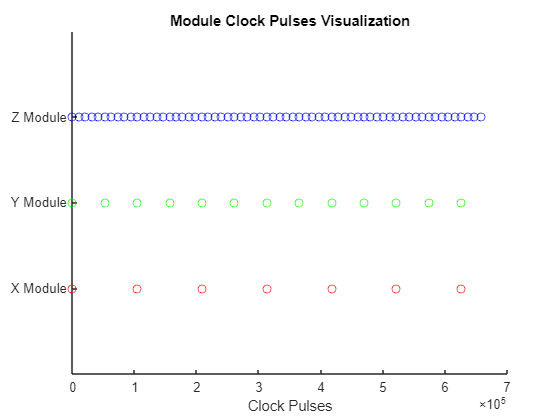


% Plotting the points for each module
figure;
hold on;
plot(Xpoints, ones(size(Xpoints)), 'ro');
plot(Ypoints, ones(size(Ypoints)) * 2, 'go');
plot(Zpoints, ones(size(Zpoints)) * 3, 'bo');
hold off;

ylim([0, 4]);
yticks([1, 2, 3]);
yticklabels({'X Module', 'Y Module', 'Z Module'});
xlabel('Clock Pulses');
title('Module Clock Pulses Visualization');